# Laboratorio 2

## Mateo Fernández (202320768), Gabriela Villalba y Gabriel Sanchez (202420981)

## Punto 1.

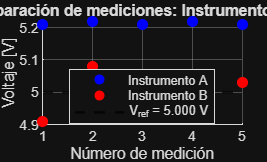

%1.1
Vref = 5.000;
A = [5.210, 5.220, 5.210, 5.220, 5.210];
B = [4.910, 5.080, 5.000, 4.980, 5.030];

function [media, desv_std, sesgo, Ea, Er, Epct] = calcular_metricas(x, Vref)
media = mean(x);
desv_std = std(x, 1);   %poblacional
sesgo = media - Vref;
Ea = abs(media - Vref);
Er = Ea / abs(Vref);
Epct = 100 * Er;
end

[media_A, std_A, sesgo_A, Ea_A, Er_A, Epct_A] = calcular_metricas(A, Vref);
[media_B, std_B, sesgo_B, Ea_B, Er_B, Epct_B] = calcular_metricas(B, Vref);

%1.2

numero_medicion = 1:5;

figure

scatter(numero_medicion, A, 45, 'b', 'filled')
hold on
scatter(numero_medicion, B, 45, 'r', 'filled')
yline(Vref, 'k--', 'LineWidth', 1.5)
hold off

xlabel('Número de medición')
ylabel('Voltaje [V]')
title('Comparación de mediciones: Instrumento A vs B')
legend('Instrumento A', 'Instrumento B','V_{ref} = 5.000 V', 'Location', 'best')
grid on


%Tabla comparativa
nombres_columnas= {'Instrumento','Media','Desv_Std','Sesgo','Ea','Er','E_pct'};
tabla_metricas = table({'A';'B'}, [media_A;media_B], [std_A;std_B], [sesgo_A;sesgo_B], ...
    [Ea_A;Ea_B], [Er_A;Er_B], [Epct_A;Epct_B],'VariableNames',nombres_columnas)

tabla_metricas = 2×7 table
    Instrumento    Media         Desv_Std          Sesgo     Ea              Er                 E_pct      
    ___________    _____    ___________________    _____    _____    __________________    ________________

       {'A'}       5.214    0.00489897948556625    0.214    0.214    0.0428000000000001    4.28000000000001
       {'B'}           5     0.0562138772902208        0        0                     0                   0



%1.3
b_A = media_A - Vref;
A_corr= A - b_A;

[media_Acorr, std_Acorr, sesgo_Acorr, Ea_Acorr, Er_Acorr, Epct_Acorr] = calcular_metricas(A_corr, Vref);

tabla_metricas_corr = table({'A (original)';'A (corregida)'}, [media_A;media_Acorr], [std_A;std_Acorr], ...
    [sesgo_A;sesgo_Acorr], [Ea_A;Ea_Acorr], [Er_A;Er_Acorr], [Epct_A;Epct_Acorr], ...
    'VariableNames', {'Version','Media','Desv_Std','Sesgo','Ea','Er','E_pct'})

tabla_metricas_corr = 2×7 table
         Version         Media         Desv_Std                  Sesgo                     Ea                      Er                    E_pct        
    _________________    _____    ___________________    _____________________    ____________________    ____________________    ____________________

    {'A (original)' }    5.214    0.00489897948556625                    0.214                   0.214      0.0428000000000001        4.28000000000001
    {'A (corregida)'}        5    0.00489897948556625    -8.88178419700125e-16    8.88178419700125e-16    1.77635683940025e-16    1.77635683940025e-14


## Punto 2.

## Punto 3.

## Punto 4.

## Punto 5.

V = 12 + 0.01*d(8)

Unrecognized function or variable 'd'.

R = 220 + 0.5*d(9)
delta_v = 0.005*(1+d(7)/10) %COTAS MAXIMAS DEL ERROR ABSOLUTO
delta_r = 0.2 + 0.05*d(8)

function potencia = calcular_potencia(V, R)
    potencia = V*V/R;
end





## Punto 6.

%a.
xS = single([1 1e3 1e8])
xD = double([1 1e3 1e8])

%b.
disp("Bytes ocupados por arreglo")
w1 = whos("xS")
w2 = whos("xD")
disp("Bytes por elemento" + newline + "xS")
w1_ele = w1.bytes/numel(xS)
disp("xD")
w2_ele = w2.bytes/numel(xD)

%c. 
disp("Separación local")
separacion_xS = eps(xS)
separacion_xD = eps(xD)
